# Integrarea Numerica

Tehnica pentru a aproxima valorile integralei definite:

####                             
$$\int_a^b f\left(x\right)\mathrm{dx}$$


Aceasta abordare devine esentiala atunci cand:

- nu putem gasi o formula exacta pentur integrare

- functia este data doar printr-un tabel de valori sau ca o functie anonima

- avem nevoie doar de o valoare aproximativa

**Tipuri:**

**1. Metode compuse/fixe (cu pas constant):**

- Impartim interbalul [a,b] in n subintervale egale.

- Aplicam o formula simpla pe fiecare subinterbal. 

- Apoi adunam toate cotributiile pt a obtine o aproximare a integralei

####                                                 
$$\int_a^b f\left(x\right)\mathrm{dx}\approx \sum_{i=1}^n \left(\mathrm{valoare}\;\mathrm{locala}\right)$$


**Tipuri de formule:**

- Dreptunghi

- Trapez

- Simpson

- *Newton-Cotes* 

**2. ****Metode adaptive / automate****:**

    In loc sa impartim intervalul in subintervale egale, metodele adaptive:

- evalueaza functia in mai multe locuri doar acolo unde este nevoie

- se opresc cand eroarea este suicient de mica

**Tipuri de abordari:**

- Adaptiv dreptunghi

- Adaptive Trapez

- Adaptive Simpson

- `adquad` (Matlab)

- *Romberg*

# **Metode Compuse/Fixe**

## Formula trapezului

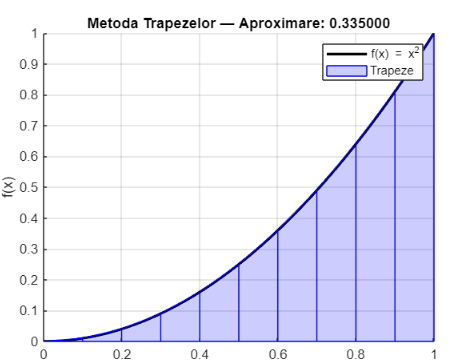

f = @(x) x.^2;       % functia de integrat
a = 0;
b = 1;
divizari = 10;       % numar subintervale
valoare_exacta = 1/3;

fprintf("Intervalul: [%g, %g] Numar de subintervale (divizari): %d\n\n", a, b, divizari);

Intervalul: [0, 1] Numar de subintervale (divizari): 10



rez_trapeze = FormulaTrapezuluiSimplu(f, a, b, divizari);
eroare_trapez = abs(rez_trapeze - valoare_exacta);
fprintf("→ Aproximare:      %.10f\n", rez_trapeze);

→ Aproximare:      0.3350000000


fprintf("→ Valoare exacta:  %.10f\n", valoare_exacta);

→ Valoare exacta:  0.3333333333


fprintf("→ Eroare absoluta: %.2e\n\n", eroare_trapez);

→ Eroare absoluta: 1.67e-03



## Formula dreptunghiului

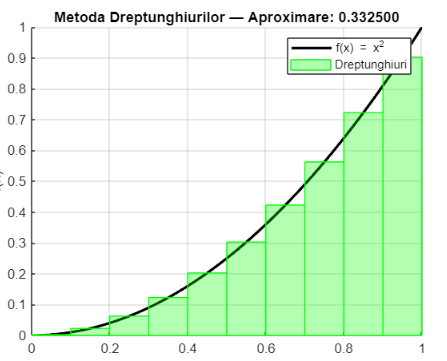

f = @(x) x.^2;       % functia de integrat
a = 0;
b = 1;
divizari = 10;       % numar subintervale
valoare_exacta = 1/3;

fprintf("Intervalul: [%g, %g] Numar de subintervale (divizari): %d\n\n", a, b, divizari);

Intervalul: [0, 1] Numar de subintervale (divizari): 10




rez_dreptunghi = FormulaDreptunghiuluiSimplu(f, a, b, divizari);
% Trapeze
eroare_trapez = abs(rez_trapeze - valoare_exacta);
fprintf("Metoda TRAPEZELOR:\n");

Metoda TRAPEZELOR:


fprintf("→ Aproximare:      %.10f\n", rez_trapeze);

→ Aproximare:      0.3350000000


fprintf("→ Valoare exacta:  %.10f\n", valoare_exacta);

→ Valoare exacta:  0.3333333333


fprintf("→ Eroare absoluta: %.2e\n\n", eroare_trapez);

→ Eroare absoluta: 1.67e-03



## Formula lui Simpson

Neaparam subintervalele trebuie sa fie un numar par deoarece se fac perechi de cate 2 regiuni pentru a construi un polinom care trece prin 3 puncte in loc de 2

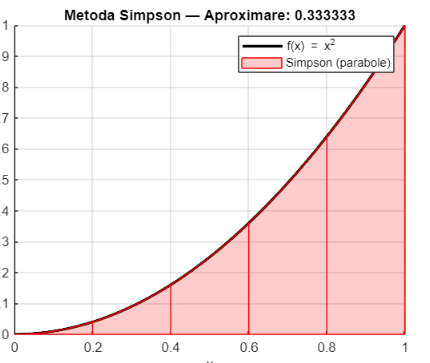

f = @(x) x.^2;       % functia de integrat
a = 0;
b = 1;
divizari = 10;       % numar subintervale
valoare_exacta = 1/3;

fprintf("Intervalul: [%g, %g] Numar de subintervale (divizari): %d\n\n", a, b, divizari);

Intervalul: [0, 1] Numar de subintervale (divizari): 10



rez_simpson = FormulaSimpsonSimplu(f, a, b, divizari);
eroare_simpson = abs(rez_simpson - valoare_exacta);
fprintf("Metoda SIMPSON:\n");

Metoda SIMPSON:


fprintf("→ Aproximare:      %.10f\n", rez_simpson);

→ Aproximare:      0.3333333333


fprintf("→ Valoare exacta:  %.10f\n", valoare_exacta);

→ Valoare exacta:  0.3333333333


fprintf("→ Eroare absoluta: %.2e\n", eroare_simpson);

→ Eroare absoluta: 0.00e+00


## Formula Newton-Cotes

Este o familie de metode numerice pentru aproximarea integralei

####                               
$$\int_a^b f\left(x\right)\mathrm{dx}$$


Ideea de baza:

- Inlocuim functie f(x) cu un polinom de interpolare (de obicei Lagrange), construit in noduri echidistante, apoi integram simbolic acest polinom

% Setari
a = 0;             % capat stanga
b = 1;             % capat dreapta
grad = 1;          % regula trapezului
f = @(x) x.^2;     % functia de integrat
exact = 1/3;       % valoare exacta pentru integrala

% Aplicam formula
[x, w] = NewtonCotes(grad, a, b);
I_approx = sum(w .* f(x));

% Afisare
fprintf("Newton-Cotes inchis cu gradul %d pe [%g, %g]\n", grad, a, b);

Newton-Cotes inchis cu gradul 1 pe [0, 1]


fprintf("→ Noduri x_i:        "); disp(x);

→ Noduri x_i:             0     1



fprintf("→ Coeficienti w_i:   "); disp(w);

→ Coeficienti w_i:      0.500000000000000   0.500000000000000



fprintf("→ Aproximare:        %.10f\n", I_approx);

→ Aproximare:        0.5000000000


fprintf("→ Valoare exacta:    %.10f\n", exact);

→ Valoare exacta:    0.3333333333


fprintf("→ Eroare absoluta:   %.2e\n", abs(I_approx - exact));

→ Eroare absoluta:   1.67e-01


# **Metode adaptive / automate:**

## Dreptunghi adaptiv

**Idee:** Aplică regula dreptunghiului pe subintervale și le împarte recursiv acolo unde este nevoie.

- **Aproximare 1:** un singur dreptunghi pe [a, b], evaluat în mijloc.

- **Aproximare 2:** două dreptunghiuri pe [a, m] și [m, b].

- **Decizie:** dacă diferența între cele două este mică (sub toleranță), acceptăm rezultatul.

- **Altfel:** împărțim intervalul în continuare.

f = @(x) x.^2;
a = 0;
b = 1;
tol = 1e-6;

I1 = FormulaDreptunghiAdaptiv(f, a, b, tol);
fprintf("Avem intervalul [%g, %g]:\n", a, b);

Avem intervalul [0, 1]:


fprintf("→ Simpson adaptiv:    %.10f\n", I1);

→ Simpson adaptiv:    0.3333333333


fprintf("→ Valoare exactă:     %.10f\n", 1/3);

→ Valoare exactă:     0.3333333333


## Trapez adaptiv

**Idee:** Se bazează pe regula trapezului, dar decide dinamic dacă trebuie subdivizat mai mult.

- Calculează integrala pe întregul interval [a, b] cu un singur trapez (`T1`).

- O compară cu rezultatul obținut din două trapeze (`T2`) aplicate pe jumătățile [a, m] și [m, b].

- Dacă diferența dintre `T1` și `T2` este suficient de mică (sub `3*tol`), acceptăm `T2` ca soluție.

- Dacă nu, **împărțim intervalul în două** și apelăm recursiv metoda pe fiecare parte.

f = @(x) x.^2;
a = 0;
b = 1;
tol = 1e-6;

I2 = FormulaTrapezAdaptiv(f, a, b, tol);
fprintf("Avem intervalul [%g, %g]:\n", a, b);

Avem intervalul [0, 1]:


fprintf("→ Trapez adaptiv:     %.10f\n", I2);

→ Trapez adaptiv:     0.3333333333


fprintf("→ Valoare exactă:     %.10f\n", 1/3);

→ Valoare exactă:     0.3333333333


## Simpson adaptiv

**Idee:** Combina acuratețea formulei Simpson cu strategie de adaptare locală.

- Se evaluează Simpson pe tot intervalul (`S1`).

- Se evaluează Simpson pe două subintervale (`S2`).

- Dacă diferența între `S1` și `S2` este mică (sub `15*tol`), se acceptă `S2 + corecție`.

- Altfel, se **împarte recursiv** intervalul în două.

f = @(x) x.^2;
a = 0;
b = 1;
tol = 1e-6;

I3 = FormulaSimpsonAdaptiva(f, a, b, tol);

fprintf("Avem intervalul [%g, %g]:\n", a, b);

Avem intervalul [0, 1]:


fprintf("→ Dreptunghi adaptiv: %.10f\n", I3);

→ Dreptunghi adaptiv: 0.3333333333


fprintf("→ Valoare exactă:     %.10f\n", 1/3);

→ Valoare exactă:     0.3333333333


## ***Extrapolarea Richardson***

    Este o metoda numerica folosita pentru a imbunatati precizia unei aproximari 

    Ideea de baza:

        -> Daca ai dpua aproximatii ale unei marimi, obtinute cu pasi diferiti, poti combina aceste valori ca sa elimini eroarea principala si sa obtii o valoarea mai buna 

## Metoda lui Romberg

Tehnica avansata de integrare numerica care imbunatateste sistematica regula trapezului prin extrapolarea Richardson. Ea ofera o precizie foarte mare pentru functii suficient de netede si derivabile.

Extrapolarea Richardson

**Ideea de baza:**

- Se porneste cu regula trapezului pe intervalul [a,b][a, b][a,b] cu un numar mic de divizări.

- Se repeta calculul **cu dublarea divizarilor**: 2, 4, 8, 16, ...

- Se construieste un **tabel** in care fiecare coloana rafineaza aproximarea anterioara prin extrapolare:

####                                     
$$R\left(k,j\right)=\frac{4^{j-1} \cdot R\left(k,j-1\right)-R\left(k-1,j-1\right)}{4^{j-1} -1}$$


**Matricea Romberg**

Este un **tabel triunghiular** in care:

- Coloana 1: valori aproximative ale integralei folosind regula trapezului cu n=1,2,4,8,…

- Coloanile urmatoare: extrapolari Richardson intre valorile de pe coloana precedenta

f = @(x) exp(-x.^2);     % functie de integrat
a = 0;
b = 1;
eps = 1e-8;

[rez_romberg, R] = Romberg(f, a, b, eps);

fprintf('Rezultat Romberg: %.10f\n', rez_romberg);

Rezultat Romberg: 0.7468241328


fprintf('Valoare exacta (aprox.): %.10f\n', integral(f, a, b, 'AbsTol', eps));

Valoare exacta (aprox.): 0.7468241328



disp('Matricea Romberg calculata:');

Matricea Romberg calculata:


disp(R);

   0.683939720585721                   0                   0                   0                   0                   0                   0                   0                   0                   0
   0.731370251828563   0.747180428909510                   0                   0                   0                   0                   0                   0                   0                   0
   0.742984097800381   0.746855379790987   0.746833709849752                   0                   0                   0                   0                   0                   0                   0
   0.745865614845695   0.746826120527467   0.746824169909899   0.746824018482282                   0                   0                   0                   0                   0                   0
   0.746584596788222   0.746824257435730   0.746824133229614   0.746824132647388   0.746824133095094                   0                   0                   0                   0                